%% Step 1: Load and Prepare the Data
clearvars; close all; clc;

% Load the original ground acceleration signal
f = linspace(0, 45, 2048); % Frequency vector
zeta = 0.5; % Bandwidth of excitation
sigma = 0.5; % Standard deviation of excitation
fn = 20; % Dominant frequency (Hz)
T90 = 1; % Envelope function at 90% duration
eps = 0.9; % Normalized peak time
tn = 50; % Duration (seconds)

% Generate the ground acceleration signal
[y, t] = seismSim(sigma, fn, zeta, f, T90, eps, tn);

% Normalize the signal for audio playback
y_normalized = (y - min(y)) / (max(y) - min(y));  
y_audio = y_normalized * 2 - 1; % Scale to range [-1, 1]

fs = 44100; % Sampling rate (44.1 kHz)

%% Step 2: Low-Pass Filtering (Remove High-Frequency Noise)
low_cutoff = 25; % Cutoff frequency (Hz) for the filter
[b_low, a_low] = butter(4, low_cutoff/(fs/2), 'low'); % 4th-order low-pass filter
y_filtered_low = filtfilt(b_low, a_low, y_audio);

%% Step 3: Notch Filtering (Remove 50 Hz Power Line Noise)
notch_freq = 50; % Power line interference (Hz)
bandwidth = 2; % Notch filter bandwidth
wo = notch_freq / (fs/2); % Normalized frequency
bw = bandwidth / (fs/2); % Normalized bandwidth
[b_notch, a_notch] = iirnotch(wo, bw);
y_filtered_notch = filtfilt(b_notch, a_notch, y_filtered_low);

%% Step 4: Wavelet Denoising (Adaptive Noise Reduction)
y_denoised = wdenoise(y_filtered_notch, 4, 'Wavelet', 'sym4', 'DenoisingMethod', 'Bayes', 'ThresholdRule', 'Soft');

%% Step 5: Adaptive Gain Control (Prevent Excessive Amplification)
gain = 80; % Adjusted gain factor
y_amplified = y_denoised * gain;

%% Step 6: Resample for Playback Duration
desired_duration = 20; % Desired playback duration (seconds)
resample_factor = desired_duration / tn; % Compute resampling factor
y_resampled = resample(y_amplified, round(fs * desired_duration), length(y_amplified));

% Clip signal to prevent distortion
y_final = max(min(y_resampled, 1), -1);

%% Step 7: Compute Noise Level (Fixed)
% Ensure y_denoised has the same length as y_final
y_denoised_resampled = resample(y_denoised, length(y_final), length(y_denoised));

% Compute Power of Signal and Noise
P_signal = rms(y_final).^2; % Power of cleaned signal
P_noise = rms(y_final - y_denoised_resampled).^2; % Estimated noise power

% Compute noise level in dB
noise_dB = 10 * log10(P_noise / P_signal);
disp(['Noise level after denoising: ', num2str(noise_dB), ' dB']);

Noise level after denoising: -1.133 dB


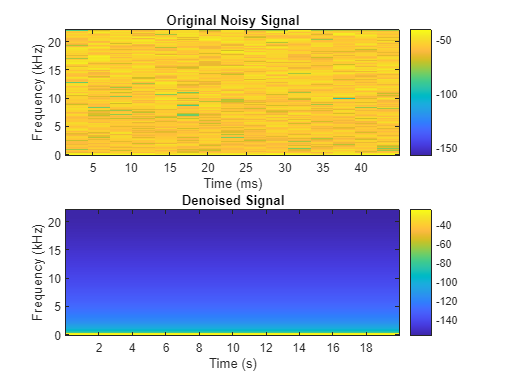



%% Step 8: Spectrogram Analysis (Before vs. After)
figure;
subplot(2,1,1);
spectrogram(y_audio, 256, [], [], fs, 'yaxis');
title('Original Noisy Signal');
colorbar;

subplot(2,1,2);
spectrogram(y_final, 256, [], [], fs, 'yaxis');
title('Denoised Signal');
colorbar;


%% Step 9: Play the Cleaned Signal
disp('Playing the denoised waveform...');

Playing the denoised waveform...


sound(y_final, fs);
pause(desired_duration);
disp('Playback complete.');

Playback complete.



%% Step 10: Save the Denoised Audio
audiowrite('ground_acceleration_denoised.wav', y_final, fs);
disp('Denoised waveform saved as "ground_acceleration_denoised.wav".');

Denoised waveform saved as "ground_acceleration_denoised.wav".
